# 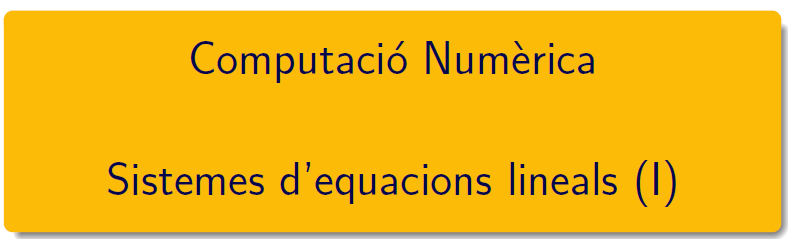

================================================================================

# TEMA 2 Àlgebra lineal numèrica (I)

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-CNLab2-3.pdf i en el document CN_full2.pdf, els podeu trobar en el campus virtual. 

## Mètodes iteratius estacionaris 

Són els mètodes de Jacobi, de Gauss-Seidel i de sobrerelaxació (SOR)


$$Ax=b \Longleftrightarrow x^{k+1}=B\,x^{k}+c\,,\quad \forall\ k\ge0\,.$$


### Submatrius D, L i U de la matriu A

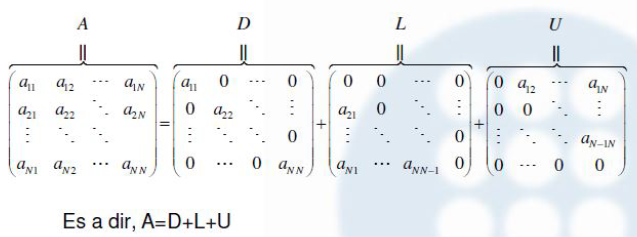   

**Exemple de les transparències - Joc de proves per a les funcions**

En una primera aproximació determineu les 10 primeres iteracions dels tres mètodes i estudieu el vector residu per cada mètode. Introduiu un test de convergència per als algoritmes de Jacobi, de Gauss - Seidel i SOR. Proveu-lo per:


$$$$A=\left( \begin{array}{rrrr}
10 & -1 & 2 & 0 \\
-1 & 11 & -1 & 3\\
2 & -1 & 10 & -1\\
0 & 3 & -1 & 8
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   6\\ 25\\-11\\ 15\end{array} \right)
\qquad \Longrightarrow \quad
x=\left(\begin{array}{r}   1\\ 2\\-1\\ 1\end{array} \right)$$
$$


**Exercici 1.** Determineu les submatrius D, L i U per a la matriu A

clearvars
A = [10 -1 2  0; -1 -11 -1 3; 2 -1 10 -1; 0 3 -1 8]; b = [6;25;-11;15];
D = diag(diag(A)); 
L = tril(A-D); 
U = triu(A-D);

**Exercici 2. **Determineu  les matrius d'iteració del mètode de Jacobi i del mètode de Gauss-Seidel del sistema Ax=b donat per 

b = [6;25;-11;15];

Matrius de Jacoi

DI = inv(D);
BJ =-DI*(L+U);
cJ = DI*b;

Matrius de Gauss-seidel

DI = inv(D+L);
Bgs =-DI*U;
cgs = DI*b;

Matrius de SOR - Gauss-Sseidel

w = 1.2;         % Aquest valor ha de ser a l'interval (0,2), w = 1 és Gauss-Seidel
C = inv(D+w*L);
Bwgs = C*((1-w)*D-w*U);
cwgs = w*C*b;

### Radi espectral 

Calculeu del valor propi de mòdul màxim en  Matlab®: consulteu eigs 

rhoJ = abs(eigs(BJ,1))          % radi = vap de mòdul màxim

rhoJ =       0.31971


rhogs = abs(eigs(Bgs,1))        % farà menys iteracions

rhogs =        0.1265


rhoW = abs(eigs(Bwgs,1))        % farà més iteracions

rhoW =       0.46862


### Pràctica 1

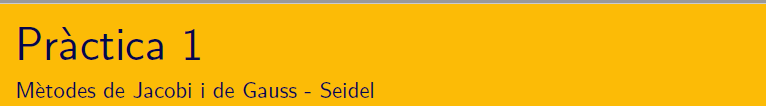

Escriviu un programa que implementi els algoritmes de Jacobi, Gauss - Seidel i SOR. 

Mètode de Jacobi

if rhoJ <1 
    k = 0;
    x = zeros(size(b));
    r = norm(A*x-b,1);
    while (k < 100 && r > 5.0e-4)
        k = k+1;
        x = BJ*x+cJ;
        r = norm(A*x-b,1);
    end
    fprintf('mètode de Jacobi convergent, en k = %d, el residu és %5.4g i el vector solució és\n',r,k)
    x
else
    fprintf('mètode de Jacobi no convergent')
end

Mètode de Gauss-Seidel

if rhogs < 1
    k = 0;
    x = zeros(size(b));
    r = norm(A*x-b,1);
    while (k < 100 && r > 5.0e-4)
        k = k+1;
        x = Bgs*x+cgs;
        r = norm(A*x-b,1);
    end
    fprintf('mètode de Gauss-Seidel convergent, en k = %d, el residu és %5.4g i el vector solució és\n',r,k)
    x
else
    fprintf('mètode de Gauss-Seidel no convergent')
end 

Mètode de SOR - Gauss-Seidel

if rhoW < 1
    k = 0;
    x = zeros(size(b));
    r = norm(A*x-b,1);
    while (k < 100 && r > 5.0e-4)
        k = k+1;
        x = Bwgs*x+cwgs;
        r = norm(A*x-b,1);
    end
    fprintf('mètode de SOR-Gauss-Seidel convergent, en k = %d, el residu és %5.4g i el vector solució és\n',r,k)
    x
else
    fprintf('mètode de SOR-Gauss-Seidel no convergent')
end 

### Pràctica 2

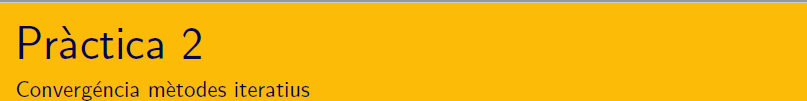

Introduiu un test de convergència per als algoritmes de Jacobi, de Gauss - Seidel i SOR. Proveu-lo 

% Ja incorporats al bucle

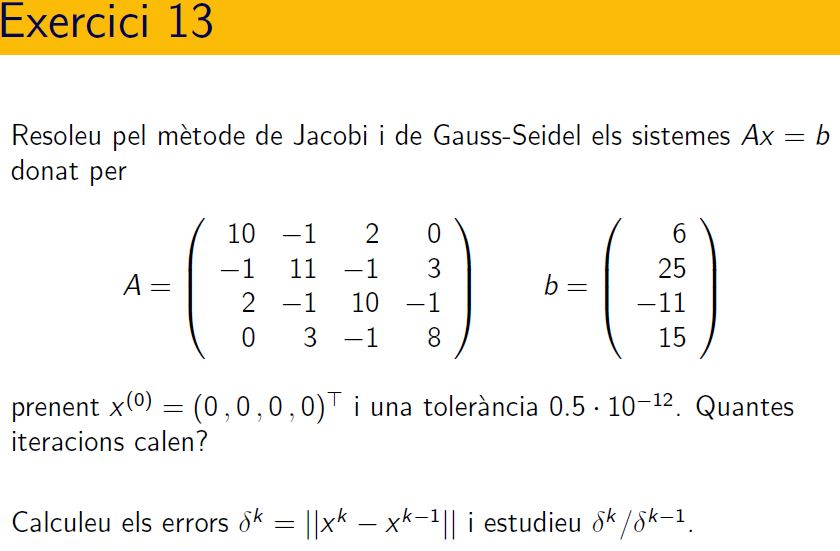

A = [10 -1 2  0; -1  11 -1 3; 2 -1 10 -1; 0 3 -1 8];
b = [6 25 -11 15]';
D = diag(diag(A)); 
L = tril(A-D); 
U = triu(A-D);

Mètode de Jacobi

DI = inv(D);
BJ =-DI*(L+U);
cJ = DI*b;
rhoJ = abs(eigs(BJ,1))

rhoJ = 0.4264

n = 100;
if rhoJ < 1
    k = 0;
    x = zeros(size(b)); y = x;
    r = norm(A*x-b,1);
    e = zeros(n,1);
    d = e;
    while (k < n && r > 0.5e-12)
        k = k+1;
        x = BJ*x + cJ;
        e(k) = norm(x-y,1);
        if k ~= 1 
            d(k) = e(k)/e(k-1);
        end
        y = x;
        r = norm(A*x-b,1);
    end
    fprintf('El mètode és convergent, en k = %d, el residu és %5.4g i el vector solució és:\n',k,r)
    x
else
    fprintf('mètode de Jacobi divergent')
end

El mètode és convergent, en k = 38, el residu és 4.459e-13 i el vector solució és:


x =     1.0000
    2.0000
   -1.0000
    1.0000


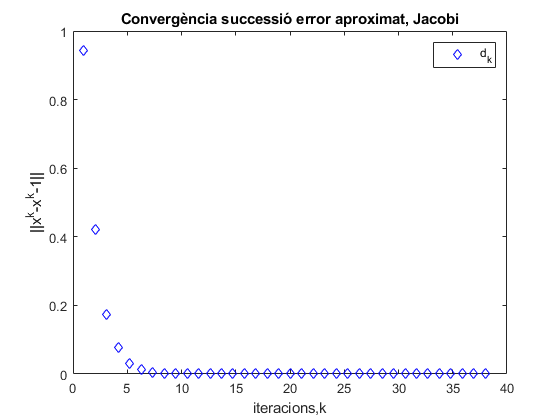

e = e(3:k); x_coord = linspace(1,k,k-2);
plot(x_coord,e,'bd');
title('Convergència successió error aproximat, Jacobi');
xlabel('iteracions,k'); ylabel('||x^k-x^k-1||');
yticks(0:0.2:1); legend('d_k');

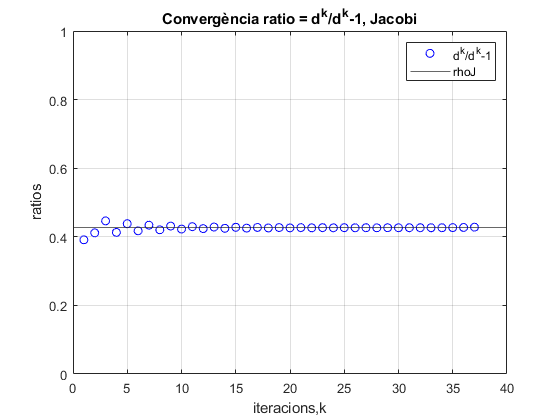

d = d(2:k); x_coord = linspace(1,k-1,k-1);
plot(x_coord,d,'bo');
grid on
title('Convergència ratio = d^k/d^k-1, Jacobi');
xlabel('iteracions,k'); ylabel('ratios');
yline(rhoJ); ylim([0 1]); yticks(0:0.2:1); 
legend('d^k/d^k-1','rhoJ');

Mètode de Gauss-Seidel

format
DI = inv(D+L);
Bgs = -DI*U;
cgs = DI*b;
rhoGS = abs(eigs(Bgs,1))

rhoGS = 0.0898

if rhoGS < 1
    k = 0;
    x = zeros(size(b)); y = x;
    r = norm(A*x-b,1);
    e = zeros(n,1);
    d = e;
    while (k < n && r > 5e-12)
        k = k + 1;
        x = Bgs*x + cgs;
        e(k) = norm(x-y,1);
        if k ~= 1 
            d(k) = e(k)/e(k-1);
        end
        y = x;
        r = norm(A*x-b,1);
    end
    fprintf('El mètode és convergent, en k = %d, el residu és %5.4g i el vector solució és:\n',k,r)
    x
else
    fprintf('mètode de Gauss-Seidel divergent')    
end

El mètode és convergent, en k = 13, el residu és 4.572e-12 i el vector solució és:


x =     1.0000
    2.0000
   -1.0000
    1.0000


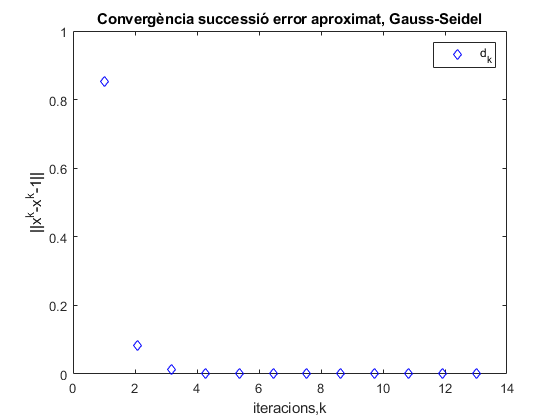

e = e(2:k);
x_coord = linspace(1,k,k-1);
plot(x_coord,e,'bd');
title('Convergència successió error aproximat, Gauss-Seidel');
xlabel('iteracions,k'); ylabel('||x^k-x^k-1||');
yticks(0:0.2:1), ylim([0 1]);
legend('d_k');

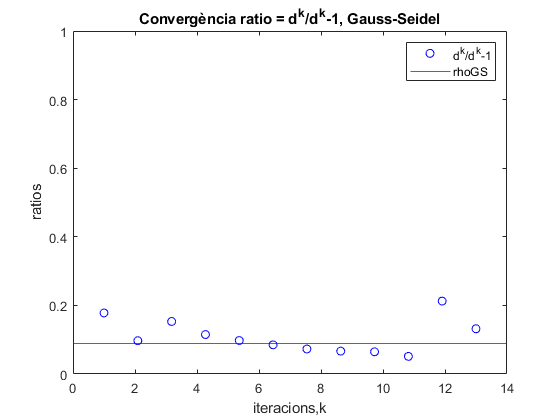

d = d(2:k); x_coord = linspace(1,k,k-1);
plot(x_coord,d,'bo');
title('Convergència ratio = d^k/d^k-1, Gauss-Seidel');
xlabel('iteracions,k'); ylabel('ratios');
yline(rhoGS); ylim([0 1]); yticks(0:0.2:1); 
legend('d^k/d^k-1','rhoGS');

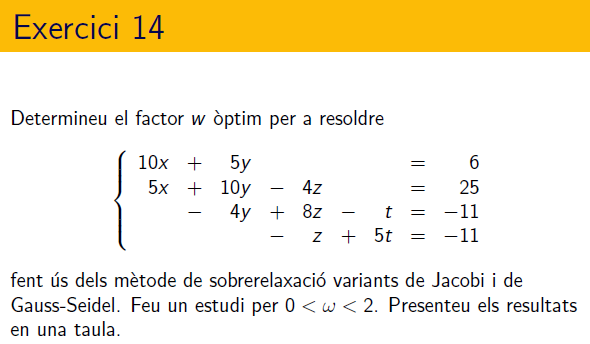

clear
A = [10 5 0 0; 5 10 -4 0; 0 -4 8 -1; 0 0 -1 5];
b = [6 25 -11 -11]'; x = linsolve(A,b)

x =    -0.7976
    2.7953
   -0.2588
   -2.2518


Jacobi amb rho = 0.6793
Òptim de tanteig per SOR_J és w =     1 amb rho = 0.6793
Gauss-Seidel amb rho = 0.4615
Òptim teòric per SOR_GS és w = 1.153 amb rho = 0.1535
Òptim de tanteig per SOR_GS és w =   1.2 amb rho =   0.2


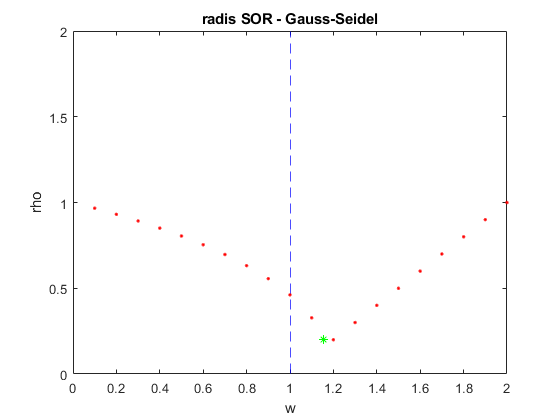

% Matrius iteració
[rhoJ, rhogs, rhoWgs, rhoWJ] = radis(A,20);

if rhoJ > 1
    fprintf('mètode de Jacobi divergent')
else
    xj = jacobifun(A,b)
end

El mètode és convergent, en k = 42, el residu és 3.679e-06 i el vector solució és:


xj =    -0.7976
    2.7953
   -0.2588
   -2.2518


if rhogs > 1
    fprintf('mètode de Gauss-Seidel divergent')
else
    xgs = gseidelfun(A,b)
end

El mètode és convergent, en k = 19, el residu és 2.493e-06 i el vector solució és:


xgs =    -0.7976
    2.7953
   -0.2588
   -2.2518


if rhoWgs > 1
    fprintf('mètode de SOR-Gauss-Seidel divergent')
else
    xw = sor_gseidelfun(A,b,1.2)
end

El mètode és convergent, en k = 11, el residu és 2.882e-06 i el vector solució és:


xw =    -0.7976
    2.7953
   -0.2588
   -2.2518


if rhoWJ > 1
    fprintf('mètode de SOR-Jacobi divergent')
end

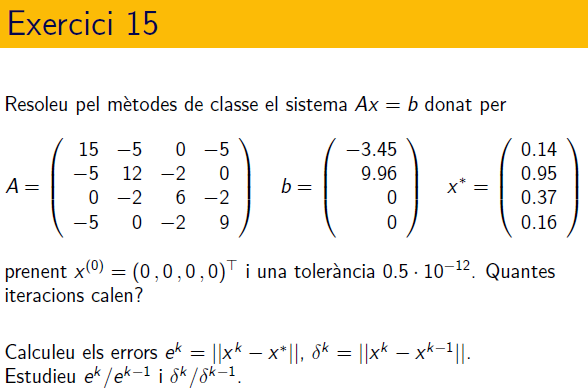

% Per fer ...
clearvars
A = [15 -5 0 -5; -5 12 -2 0; 0 -2 6 -2; -5 0 -2 9];
b = [-3.45;9.96;0;0]; y = [0.14;0.95;0.37;0.16];
D = diag(diag(A)); 
L = tril(A-D); 
U = triu(A-D);
DI = inv(D);
BJ =-DI*(L+U);
cJ = DI*b;
rhoJ = abs(eigs(BJ,1))

rhoJ = 0.6736

n = 100;
if rhoJ < 1
    k = 0;
    x = zeros(size(b)); y = x;
    r = norm(A*x-b,1);
    e = zeros(n,1);
    d = e;
    while (k < n && r > 0.5e-12)
        k = k+1;
        x = BJ*x + cJ;
        e(k) = norm(x-y,1);
        if k ~= 1 
            d(k) = e(k)/e(k-1);
        end
        y = x;
        r = norm(A*x-b,1);
    end
    fprintf('El mètode és convergent, en k = %d, el residu és %5.4g i el vector solució és:\n',k,r)
    x
else
    fprintf('mètode de Jacobi divergent')
end

El mètode és convergent, en k = 78, el residu és 4.927e-13 i el vector solució és:


x =     0.1400
    0.9500
    0.3700
    0.1600


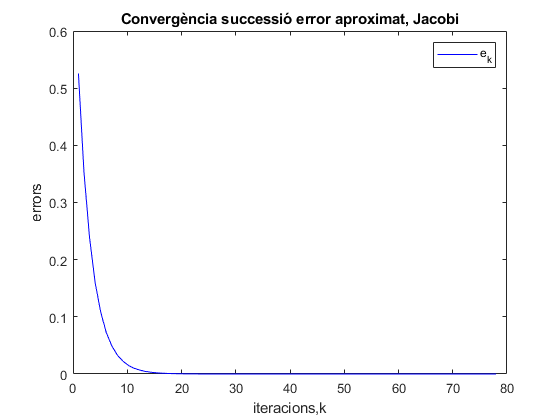

e = e(3:k); x_coord = linspace(1,k,k-2);
plot(x_coord,e,'b');
title('Convergència successió error aproximat, Jacobi');
xlabel('iteracions,k'); ylabel('errors');
legend('e_k');

`Document preparat per M. Àngela Grau Gotés, 10 de març de 2021`